clear all;
close all;
clc;

# StanDep thresholding reactions

This code is designed to execute the global thresholding algorithm. Created by Pablo Tejero during his internship at MaCSBio.

It is necessary to use COBRAToolbox, a MATLAB toolbox specifically for metabolic network analysis and model reconstruction. The Gurobi solver is also used, although MATLAB's built-in solver can be used.

## Gurobi setup and Cobra Toolbox initialization

The Gurobi solver is initialised, as well as COBRAToolbox.

gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.45.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   --------------------------------------------------------

The objective is linear

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab');
changeCobraSolver('gurobi', 'all');


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
Gurobi error 10009: License expired 2024-05-14
Please consult the Gurobi Quick Start Guide for details on setting up a license.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
Gurobi error 10009: License expired 2024-05-14
Please consult the Gurobi Quick Start Guide for details on setting up a license.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 

## Load data

- Gene expression data.

- Housekeeping gene lists: both Eisenberg and Housekeeping Atlas lists one.

- Housekeeping enzymes: Calculated based on the AND rules of the Genome-Scale Metabolic Model.

- Model: Genome-Scale Metaoblic Model, Human1 v1.17 is used in this project. 

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
data = readtable("data_TPM.xlsx");
h_k_g = readtable('NM2ENSG.xlsx');

hk_gene_new = readtable('ENS_ID_HKG.xlsx');
hk_gene_new = table2cell(hk_gene_new);

test_HKG = readtable('journal.pcbi.1010295.s014.xlsx', 'Sheet','Human');
test_HKG = table2cell(test_HKG);

model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
% model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
% model_Alicia = model_Alicia.myModel;

## Ensure the model does not contain blocked reactions

The Genome-Scale Metabolic model may contain blocked reactions, which could affect further analysis. A pruned model is obtained using findFluxConstentSubset function from COBRATolbox. 

%[fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
%model_p = fluxConsistModel; % load the new model with no blocked reactions
%save('model_p.mat', 'model');
model_p = load('model_p.mat');
model_p = model_p.model_p;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
%model_genes = model.genes;
cd(currentFolder)

## Preprocessing

Expression data should be normalized to make the interpretation easier. A new matrix is created, including a first column called 'gene' including the ENSEMBL_IDs, and one column for each sample. The fene expression data is normalized based on this equation:

*normalized_data = log10(data + 1)*

The 1 is added to avoid obtaining -inf values (log10(0)) that can affect the results. Those normalized values are added to their correspondent genes and samples. The normalized table is created. 

% Colect the data needed to create the table
Ensembl_id = data(:, 1);
NamesSample = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
logged_data = log10(data_to_log + 1); 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(logged_data)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = NamesSample; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

## Processing the Genome-Scale Metabolic Models

Metabolic gene expression is extracted based on both, pruned and unpruned model. Those two matrices will be used afterwards.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PRUNED MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
geneExpressionMatrix_P = [];

for i = 1: width(NamesSample)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

% Convert the results into a table
metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', NamesSample);
% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 
% metabolic genes pruned extra column with the means
sampleNames = metabolic_genes_P.Properties.VariableNames;

## StanDep

Change the name of the column that contains the Ensembl_ID to gene, and normalize the data, ACTUALLY IT IS ALREADY NORMALIZED, SO NO NEEDED. ASK THIS

%Ensuring that the first colum is names 'gene' 
data_met = metabolic_genes_P;
data_met.gene = data_met.Properties.RowNames;
columnNames = ['gene', data_met.Properties.VariableNames];
data_met = data_met(:, columnNames);
data_met.gene_1 = [];
data_met.Properties.RowNames = {};
%Although this is not documented clearly, standep will perform a log10 on
%the expression data. To ensure that this does not introduce negative
%numbers we add 1 everywhere.
datalog10 = data_met;
%datalog10{:,2:end} = datalog10{:, 2:end};%(datalog10{:,2:end}+1)

Define the limits of the bins:

%Standep requires us to define the bin boundaries. IMPORTANTLY these
%boundaries have to be in a log scale...
maxlog10 = max(max(table2array(datalog10(:,2:end))));
edgeX = linspace(0,maxlog10,11); %If we want 10 bins we need 11 
edgeX = round(edgeX,1); %These are our bin bounds!

Pre-processing of the data for Standep

%Standep requires a very specific pre-processing for the inputs!
%1st, the RNA data structure
rnaData = struct();
rnaData.gene = data_met.gene;
rnaData.value = table2array(data_met(:,2:end));
rnaData.valuebyTissue = table2array(data_met(:,2:end));
rnaData.Tissue = data_met.Properties.VariableNames(2:end)';

Pre-processing of the metabolic model

%2nd the model data structure
modelData = getModelData(rnaData,model_p);

Pre-processing of the enzyme data 

%3rd the enzyme data structure
spec = getSpecialistEnzymes(model_p);  
prom = getPromEnzymes(model_p);
enzymeData = comparePromiscuousSpecific(spec,prom,modelData);

Set the parameters for the clustering analysis

% We then set our parameters...
distMethod = 'euclidean'; % distance method  maybe think one more robust than euclidean.
linkageMethod = 'complete'; % linkage metric for hierarchical clustering
k = 10;

Clustering analysis

close all %This is important to ensure that all standep plots have the right number to be saved if we wish
clustObj = geneExprDist_hierarchy(enzymeData,[],edgeX,k,distMethod,linkageMethod)

Identify core reactions and calculate ubiquity score?

[coreRxnMat,enzTis,cutOff,thr] = models4mClusters1(clustObj,enzymeData.Tissue,model_p,edgeX,[],[],false,0,[1 1]); %CoreRxnMat defines the core set of reactions in a general sense
[ubiScore,uScore] = getUbiquityScore_2022(clustObj,edgeX,model_p); %ubiScore is the ubiquity score per rxns to use in mCadre!

## CREATE Context-Specific Model with FASTCORE

Mean_coreReact = cell2mat(model_p.rxns(coreRxnMat(:, 48) == 1));
%Mean_coreReact = cell2mat(CoreReact_Sample{1, 49});
% CoreReact_IMR(end+1) = findRxnIDs(model_p, 'biomass_maintenance');
FASTCORE_MEAN_STANDEP = fastcore(model_p, Mean_coreReact);
save('FASTCORE_MEAN_STANDEP.mat', 'FASTCORE_MEAN_STANDEP');

# HOUSEKEEPING GENES 

Cophenetic correlation coeffcient using complete linkage and euclidean distance = 0.9477


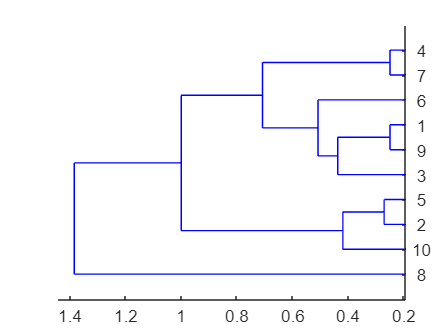

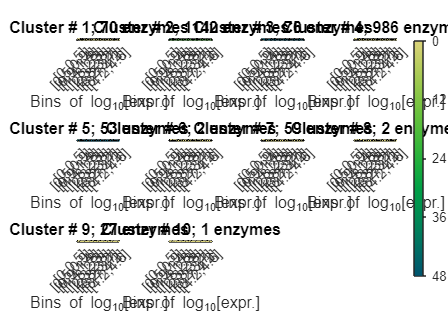

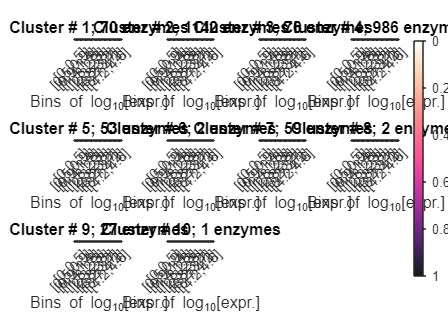

clustObj = struct with fields:
     Distribution: [2418×10 double]
          numObjs: [2418×1 double]
          objects: {2418×1 cell}
       objectMaps: {2418×1 cell}
                C: [10×10 double]
           cindex: [2418×1 double]
             Data: [2418×48 double]
    numObjInClust: [10×1 double]


hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));


% Use this function to find the housekeeping reactions names

Top 25th percentile for the data = 0.2038
Mean of Data = -0.2683
Std. Dev. of Data = 0.1887
fraction selected = 0.9988
fraction selected = 0.0000
fraction selected = 0.9981
fraction selected = 1.0000
fraction selected = 0.0004
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 0.9985
fraction selected = 0.0208


HKG_react = findRxnsFromGenes_Alicia(model_p, hkg_met); % Gives a structure, so the for loop to extract the names

Top 25th percentile for the data = 0.2038
Mean of Data = -0.2683
Std. Dev. of Data = 0.1887



% Extract unique housekeeping reaction names
fields = fieldnames(HKG_react);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};

0 = solution.stat
1 = solution.origStat


LP10: Adaptive scaling factor did not work, switching to fixed scaling factor of 1e4
            full: [46673×1 double]
             obj: NaN
           rcost: [46673×1 double]
            dual: [30392×1 double]
           slack: []
          solver: 'pdco'
       algorithm: 'default'
            stat: 0
        origStat: 1
    origStatText: []
            time: 2.9670
           basis: []



0 = sol.stat
1 = sol.origStat


    cellArray = HKG_react.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end


Input: string of single gene or cell array of multiple genes


% Just want the name one time
housekeep_react_unique = unique(housekeep_react);


HK_rxns = find_housekeeping_reactions(model_p, hkg_met, 'strict')

## Obtain core-reactions name

% Dimensions of coreRxnMat
[numReactions, numSamp] = size(ubiScore);

% Initialize the output matrix with empty cells
reactNames = cell(numReactions, numSamp);

HK_rxns = 1×1836 cell array
    {'MAR03905'}    {'MAR03907'}    {'MAR04097'}    {'MAR04108'}    {'MAR04133'}    {'MAR04281'}    {'MAR04388'}    {'MAR08357'}    {'MAR04360'}    {'MAR04365'}    {'MAR04368'}    {'MAR04371'}    {'MAR04381'}    {'MAR04391'}    {'MAR03989'}    {'MAR08592'}    {'MAR08589'}    {'MAR03944'}    {'MAR04130'}    {'MAR04131'}    {'MAR04132'}    {'MAR04303'}    {'MAR04414'}    {'MAR08767'}    {'MAR04383'}    {'MAR04400'}    {'MAR04401'}    {'MAR04402'}    {'MAR04706'}    {'MAR08768'}    {'MAR08341'}    {'MAR08344'}    {'MAR08727'}    {'MAR08729'}    {'MAR06537'}    {'MAR03853'}    {'MAR03857'}    {'MAR04087'}    {'MAR04091'}    {'MAR08497'}    {'MAR08500'}    {'MAR08501'}    {'MAR08502'}    {'MAR08503'}    {'MAR08504'}    {'MAR08506'}    {'MAR08507'}    {'MAR08508'}    {'MAR08509'}    {'MAR08511'}    {'MAR08516'}    {'MAR00153'}    {'MAR03212'}    {'MAR03797'}    {'MAR04331'}    {'MAR04459'}    {'MAR04460'}    {'MAR09804'}    {'MAR03163'}    {'MAR04052'}    {'MAR043


% Iterate over each element of coreRxnMat
for i = 1:numReactions
    for j = 1:numSamp
        if ubiScore(i, j) >= 1
            % If the element is 1, find the corresponding reaction name
            reactNames{i, j} = model_p.rxns{i};
        else
            % Optional: You can leave the cells empty or put a marker to indicate absence
            reactNames{i, j} = ''; % Assign empty or a specific marker
        end
    end
end

% reactNames now contains the reaction names for each "1" in coreRxnMat

% Obtain the mean
Bool_reactions = ubiScore >= 1;
total_coreReact_sample = sum(Bool_reactions);
mean_coreReact = round(mean(total_coreReact_sample,2))

## Check the accuracy

% Initialize the structure to store the results
comparisonResults = struct("numMatches", [], 'matchedElements', [], 'percentage', []);
totalReferenceElements = numel(HK_rxns);


mean_coreReact = 4660

% Iterate over each column of largeCellArray
for i = 1:size(reactNames, 2)  % Assuming you want to compare by columns
    % Get all the elements of the current column
    currentColumnElements = reactNames(:, i);
    % Flatten the cell array to ensure proper comparison
    currentColumnElements = vertcat(currentColumnElements{:});
    
    % Find matches between the reference elements and the current elements
    matches = ismember(HK_rxns, currentColumnElements);
    
    % Store the results in the structure
    comparisonResults(i).numMatches = sum(matches);
    comparisonResults(i).matchedElements = HK_rxns(matches);
    comparisonResults(i).percentage = (comparisonResults(i).numMatches / totalReferenceElements) * 100;
end

% Generate a table with the match percentages
percentages = [comparisonResults.percentage]';
comparisonTable = table(percentages, 'VariableNames', {'HK_R_acc_SD'});

% Save the table to an Excel file
writetable(comparisonTable, "MatchComparisonResults.xlsx", 'WriteRowNames', false);

% Obtain the mean of housekeeping reactions inclusion
mean_coreHKR = round(mean(arrayfun(@(x) x(1).numMatches, comparisonResults)));


mean_coreHKR = 1765